# **TALLER 13, 14 y 15**

Ana María Palacio 

**Introducción: Péndulo simple con fuerza tangencial.**

El objetivo de este taller es resolver numéricamente, aplicando el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado no lineal de un péndulo simple con fuerza tangencial (ver sección 7.3.1 del texto guía) en un archivo Live Script de MATLAB e interpretar los resultados cambiando diversos parámetros a partir de la respuesta temporal y retrato de fase. 

Donde, θ es el ángulo (en radianes, rad) respecto a la posición vertical, ω es la velocidad angular (en radianes por segundo, rad/s) y *u* es la fuerza externa aplicada tangencialmente. Los parámetros son la masa (*m*, en kilogramos), la longitud (*l*, en metros), la aceleración de la gravedad (*g*, en m/s2) y f es el coeficiente de fricción viscosa (*f*, N/(ms-1) o kg/s). Suposición: el hilo es rígido y tiene una masa que se puede despreciar, por lo que el péndulo puede tomar posiciones superiores.

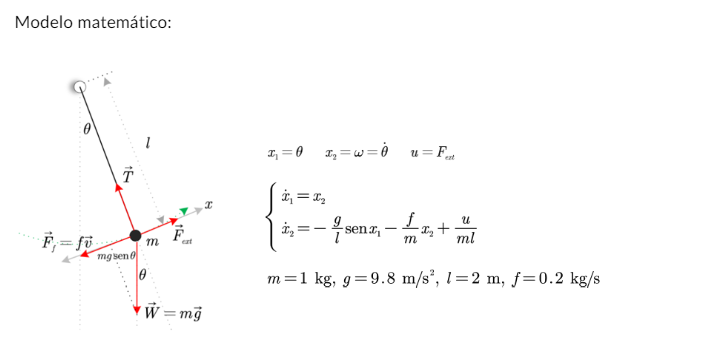

**Metodología:** Se plantean 10 puntos donde en cada uno se busca resolver numéricamente, aplicando el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado no lineal de un péndulo simple con fuerza tangencialse y se realiza además, gráficas de la solución para verificar resultados. Por último, se realiza un análisis de los datos obtenidos  indicando cómo influye cada coeficiente y su variación en el comportamiento del gráfico y qué significa esto dentro del modelo de péndulo

Puntos a analizar:

- Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para qué valor máximo de la entrada el sistema rotará indefinidamente?

- Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

- Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

- Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

- Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

- Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

- Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

- Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB.

- Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

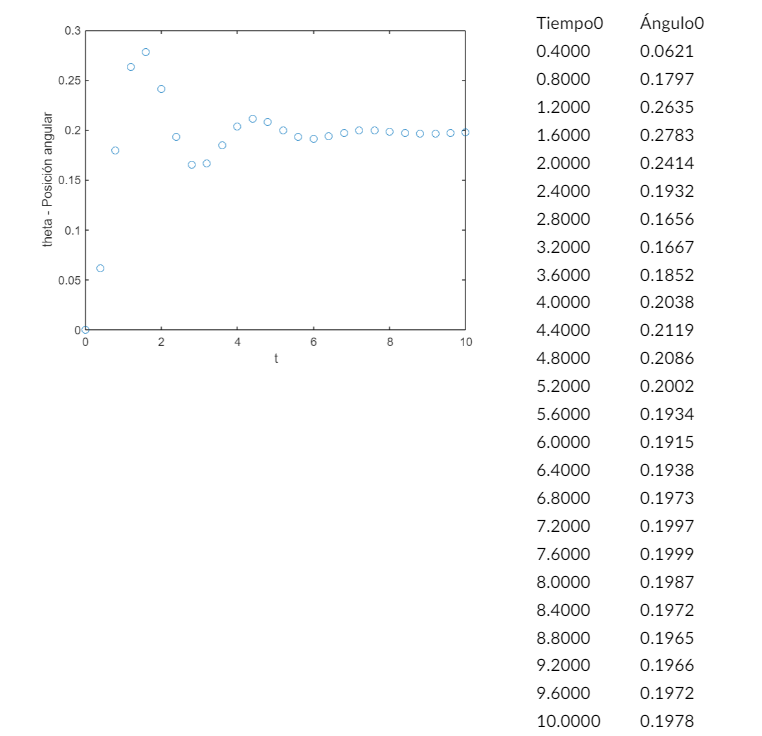

10. Montar un experimento en casa de un péndulo con entrada igual cero y un ángulo inicial entre 20 y 60°, y hallar los parámetros *l* y *f* si se conocen *m* y *g*. Es decir, suponer que no se sabe la longitud. Al final, mostrar la discrepancia de la longitud. ¿Por qué si no hay entrada el experimento no sirve para hallar *f* y *m* como en la tarea anterior?

**PUNTO 1: **parte 1

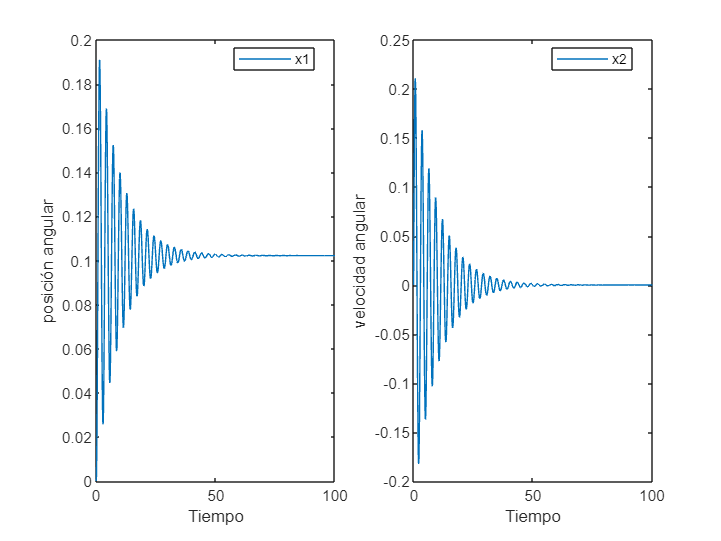

syms x1(t) x2(t)

g=9.8;
l=2;
m=1;
f=0.2;
u=1;

%ecuaciones
ecu1= x2;
ecu2= (-g/l)* sin(x1) - (f/m)*x2 + (u/(m*l));


F= odeFunction([ecu1, ecu2], [x1, x2]);

%Tiempo
t0=0;
tf=100;

%Paso
h=0.1;
t=t0:h:tf;


%Condición inicial
CI= [0,0];

[t, Sol]= ode45 (F, t, CI);

x1_Sol= Sol(:,1);
x2_Sol= Sol(:,2); 

%Gráfica
figure
subplot(1,2,1)
plot(t, x1_Sol)
xlabel ("Tiempo")
ylabel ("posición angular")
legend ("x1", "Location", "best")
hold on
subplot (1,2,2)
plot (t, x2_Sol)
xlabel ("Tiempo")
ylabel ("velocidad angular")
legend ("x2", "Location", "best")

**PUNTO 1: **parte 2

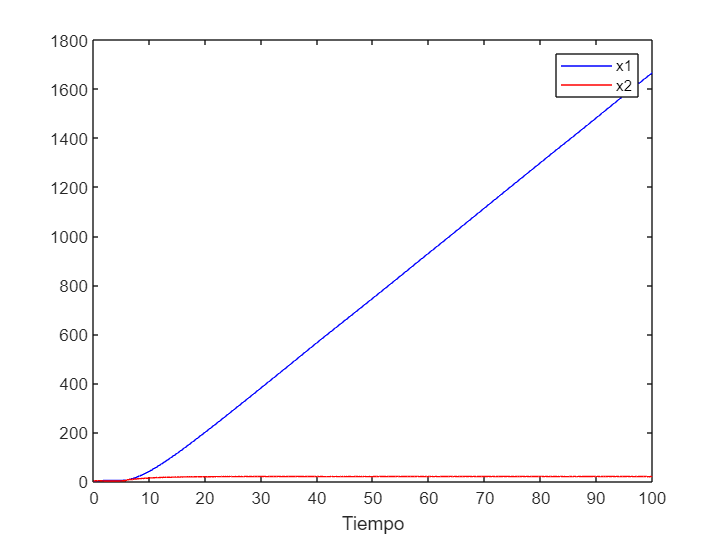

syms x1(t) x2(t)

m = 1; 
g = 9.8; 
l = 2; 
f= 0.2; 
u = 7.55;

%ecuaciones
ecu1= x2;
ecu2= (-g/l)* sin(x1) - (f/m)*x2 + (u/(m*l));


F= odeFunction([ecu1, ecu2], [x1, x2]);

%Tiempo
t0=0;
tf=100;

%Paso
h=0.1;
t=t0:h:tf;


%Condición inicial
CI= [0,0];

[t, Sol]= ode45 (F, t, CI);

x1_Sol= Sol(:,1);
x2_Sol= Sol(:,2); 

%Gráfica

figure
plot(t,x1_Sol,'b',t,x2_Sol,'r')
xlabel('Tiempo')
legend('x1', 'x2')

**Conclusión:**

Resultados:

- La curva se estabilizó en una parte diferente al origen. 

- A medida que pasa el tiempo, las oscilaciones disminuyen.

Análisis: 

- Se puede observar que la fuerza ejercida no es lo suficientemente poderosa para hacerlo girar.

- en la primera fase el péndulo oscila luego de un tiempo por la fricción y la oscilación en otro punto diferente al origen disminuye.

- La variable "u" muestra una oscilación. Cuando el valor de "u" aumenta, el tipo de movimiento cambia y comienza a girar. Este cambio se observa claramente cuando el valor de u está entre 7 y 8 aproximadamente.

- Si a esta fuerza "u" le ponemos 7.5 se comporta muy similar. Con 7.55 el pendulo empieza a girar indefinidamente y tiende a infinito.

- En este caso, la fuerza externa  se mueve de manera oscilante en un rango que va desde 1 hasta 7.55, y después de 7.55, el péndulo comuienza a girar.

**PUNTO 2:**

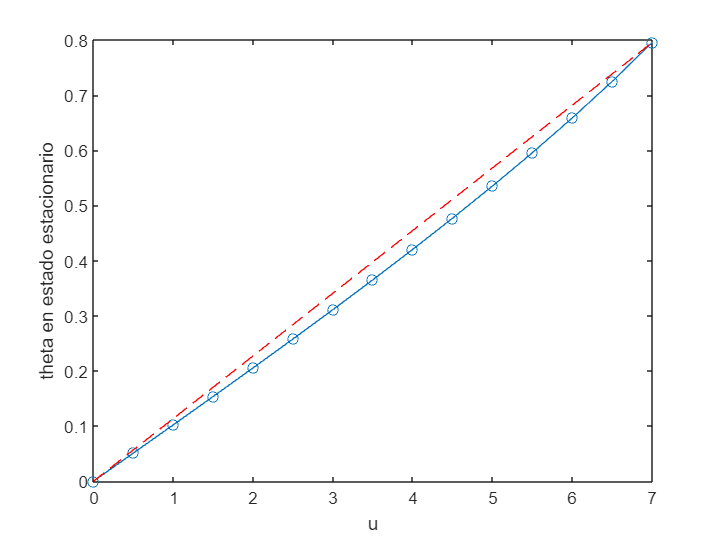

clear
syms x1(t) x2(t)

g=9.8;
l=2;
m=1;
f=0.2;
u=1;

ecu1=x2;

val_u=0:0.5:7;
N=length(val_u);

tiempo=0:0.1:100;
CI= [0 0];

for i=1:N %i es iterador de 1 en 1 hasta lograr el valor de N
    u=val_u(i);
    ecu2= (-g/l)* sin(x1) - (f/m)*x2 + (u/(m*l));
    F= odeFunction([ecu1, ecu2], [x1, x2]);
    [t, Sol]= ode45 (F, tiempo, CI);
    theta(i)=Sol(end,1);
end
figure
plot (val_u, theta, 'o-'); %,'o-',[0 val_u(end)],[0 theta(end), 'r--']
hold on
plot ([0, val_u(end)],[0, theta(end)], 'r--')
xlabel ('u')
ylabel ('theta en estado estacionario')

**Conclusión:**

Análisis: 

- Si aumento la fuerza no va a tener un crecimiento lineal. 

- Cuando "u" disminuye, es decír, es menor o igual a 7.55, el péndulo sigue oscilando como siempre

- Pero cuando "U" es mayor a este valor, el péndulo da vueltas en círculos en lugar de moverse de un lado a otro.

**PUNTO 3**

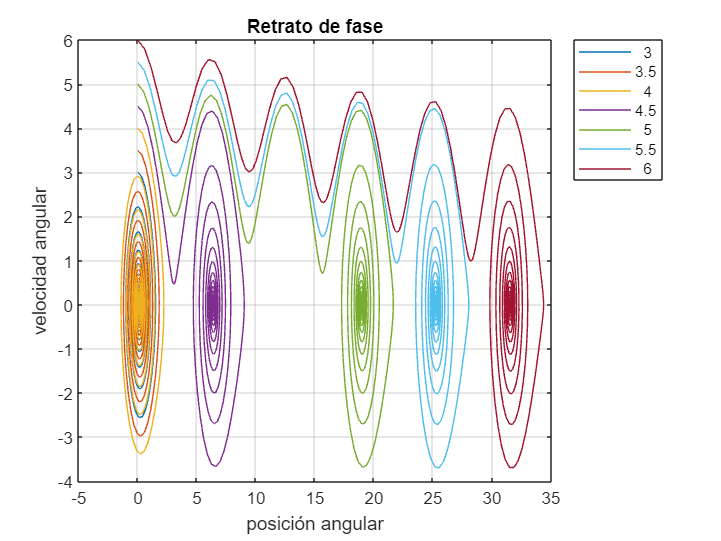

clear
syms x1(t) x2(t)

g=9.8;
l=2;
m=1;
f=0.2;
u=1;


%ecuaciones
ecu1= x2;
ecu2= (-g/l)* sin(x1) - (f/m)*x2 + (u/(m*l));

F= odeFunction([ecu1, ecu2], [x1, x2]);

%Tiempo
t0=0;
tf=100;

%Paso
h=0.1;
t=t0:h:tf;

%Condición inicial
CI= [3, 3.5, 4, 4.5, 5, 5.5, 6];

figure

for i=CI
    [t, Sol]= ode45 (F, t, [0 i]); 

x2_Sol= Sol(:, 2); 
x1_Sol=Sol(:, 1);
plot (x1_Sol, x2_Sol)
hold on
xlabel("posición angular")
ylabel ("velocidad angular")
title ("Retrato de fase")
grid on
end
legend (num2str(CI'), 'Location', 'bestoutside');

**Conclusión:**

Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

Resultados:

- 4.5 es el valor de la frecuencia angular inicial en el que el péndulo da una vuelta.

- 5 es el valor en el que el péndulo da 3 vueltas.

Análisis: 

-  Se observa que entre mayor sea la velocidad angular inicial, el péndulo oscilará máss y dará mas vueltas.

**PUNTO 4**

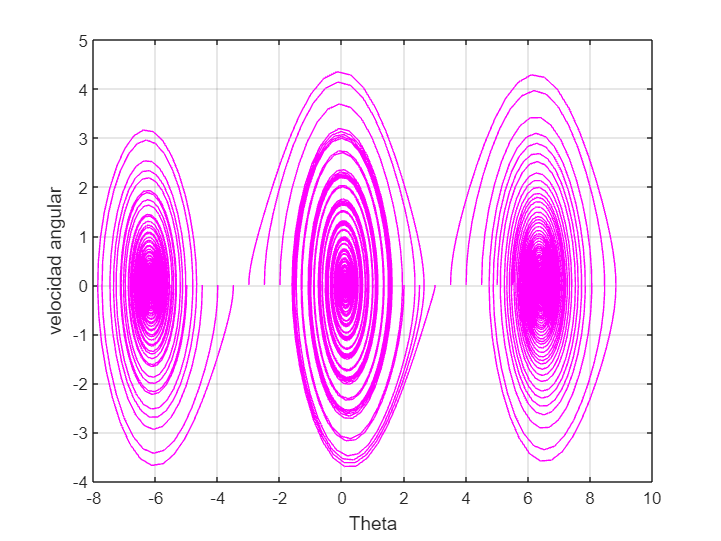

clear
syms x1(t) x2(t)

g=9.8;
l=2;
m=1;
f=0.2;
u=1;


%ecuaciones
ecu1= x2;
ecu2= (-g/l)* sin(x1) - (f/m)*x2 + (u/(m*l));

F= odeFunction([ecu1, ecu2], [x1, x2]);

%Tiempo
t0=0;
tf=100;

%Paso
h=0.1;
t=t0:h:tf;

%Condición inicial
CI= -6:0.5:6;

figure

for i=CI
    [t, Sol]= ode45 (F, t, [i 0]); 

x2_Sol= Sol(:, 2); 
x1_Sol=Sol(:, 1);
plot (x1_Sol, x2_Sol, 'm')
hold on
xlabel("Theta")
ylabel ("velocidad angular")
grid on
end

**Conclusión:**

Análisis: 

- Cuando los valores de la condición inicial varían entre -6 y 6 con un aumento de 0.5, el péndulo comienza a oscilar y se acerca a su punto de equilibrio a medida que las oscilaciones se reduce. 

- Sin importar desde que punto cocmienza la curva, el péndulo siempre se estabilizará y tratará de llegar a un punto de equilibrio.

**PUNTO 5. VARIACIÓN LONGITUD**

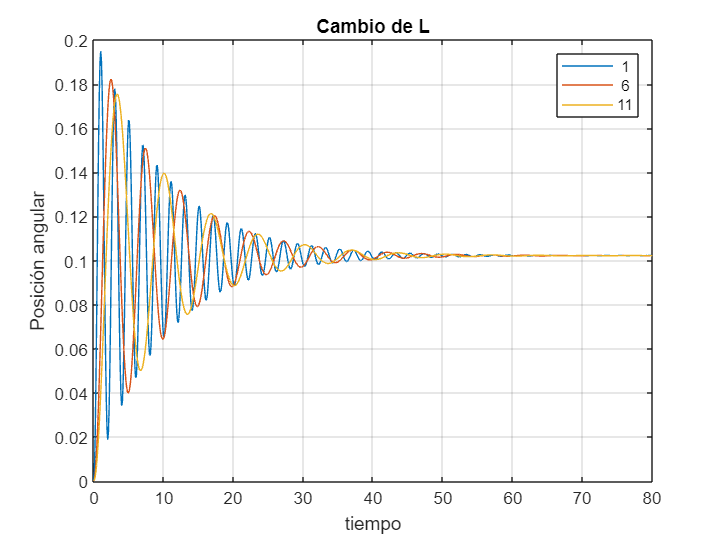

clear
syms x1(t) x2(t)

g=9.8;
l=1:5:15;
m=1;
f=0.2;
u=1;


%Tiempo
t0=0;
tf=80;

%Paso
h=0.1;
t=t0:h:tf;

%Condición inicial
CI= [0 0];

figure

for i=l
    ecu1= x2;
    ecu2= (-g/i) * sin(x1) - (f/m)*x2 + (u/(m*i));

    F= odeFunction([ecu1, ecu2], [x1, x2]);
    [t, Sol]= ode45 (F, t, CI); 

x1_Sol=Sol(:, 1);


plot (t, x1_Sol)
hold on
xlabel("tiempo")
ylabel ("Posición angular")
title ("Cambio de L")
grid on
end
legend (num2str(l'));

**Conclusión:**

Resultados:

- A medida que aumenta el valor de L, las oscilaciones son más cortas.

- A mayor longitud, habrá un mayor espacio de oscilación.

- Entre meno longitud, habrá mas oscilaciones.

- Sin importar el largo de la cuerda, las oscilaciones parecen estabilizarse casi al mismo tiempo.

**PUNTO 6. VARIACIÓN MASA**

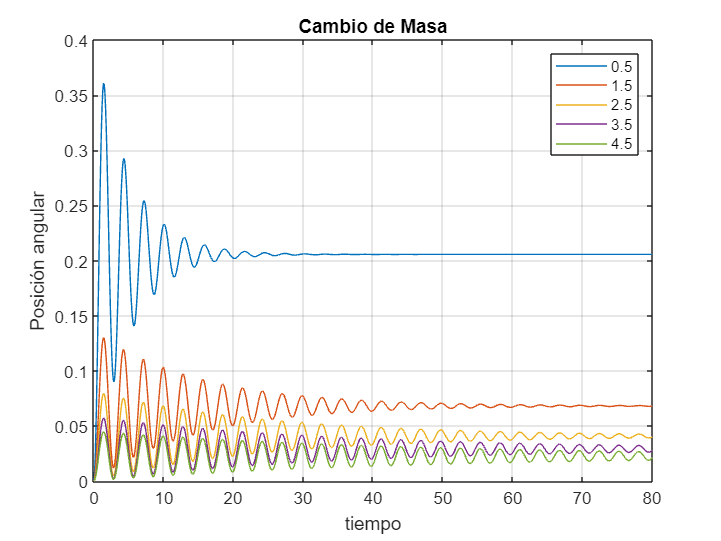

clear
syms x1(t) x2(t)

g=9.8;
l=2;
m=0.5:1:5;
f=0.2;
u=1;


%Tiempo
t0=0;
tf=80;

%Paso
h=0.1;
t=t0:h:tf;

%Condición inicial
CI= [0 0];

figure

for i=m
    ecu1= x2;
    ecu2= (-g/l) * sin(x1) - (f/i)*x2 + (u/(i*l));

    F= odeFunction([ecu1, ecu2], [x1, x2]);
    [t, Sol]= ode45 (F, t, CI); 

x1_Sol=Sol(:, 1);


plot (t, x1_Sol)
hold on
xlabel("tiempo")
ylabel ("Posición angular")
title ("Cambio de Masa")
grid on
end
legend (num2str(m'));

**Conclusión:**

Análisis:

- A medida que el valor de la masa sea menor, la posción aumentará, se estabilizará en un punto mayor y sus osciclaciones serán más grandes.

- Cuando la masa aumenta, tiende a oscilar más cerca a cero y además, tarda más tiempo en estabilizarse.

- En esta grafica también podemos concluir que si la masa es mayor, el desplazamiento angular será menor.

**PUNTO 7. VARIACIÓN DE FRICCIÓN VISCOSA**

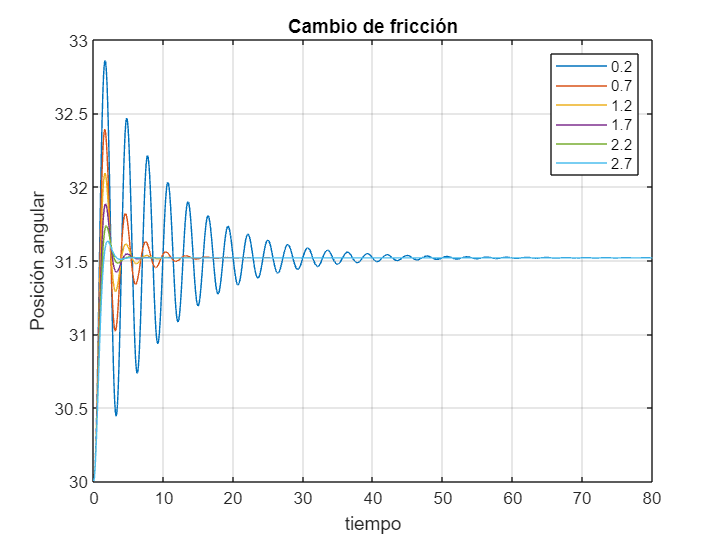

clear
syms x1(t) x2(t)

g=9.8;
l=2;
m=1;
f=0.2:0.5:3;
u=1;


%Tiempo
t0=0;
tf=80;

%Paso
h=0.1;
t=t0:h:tf;

%Condición inicial
CI= [30 0];

figure

for i=f
    ecu1= x2;
    ecu2= (-g/l) * sin(x1) - (i/m)*x2 + (u/(m*l));

    F= odeFunction([ecu1, ecu2], [x1, x2]);
    [t, Sol]= ode45 (F, t, CI); 

x1_Sol=Sol(:, 1);


plot (t, x1_Sol)
hold on
xlabel("tiempo")
ylabel ("Posición angular")
title ("Cambio de fricción")
grid on
end
legend (num2str(f'));

**Conclusión:**

Análisis:

- A medida que el valor de la fricción sea menor, el desplazamiento angular será mayor y tarda más tiempo en estabilizarse.

- Entre mayor sea el valor de la fricción viscosa, menor será su desplazamiento y sus oscilaciones serán menores.

**PUNTO 8.**

¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB.

**Solución numérica:**

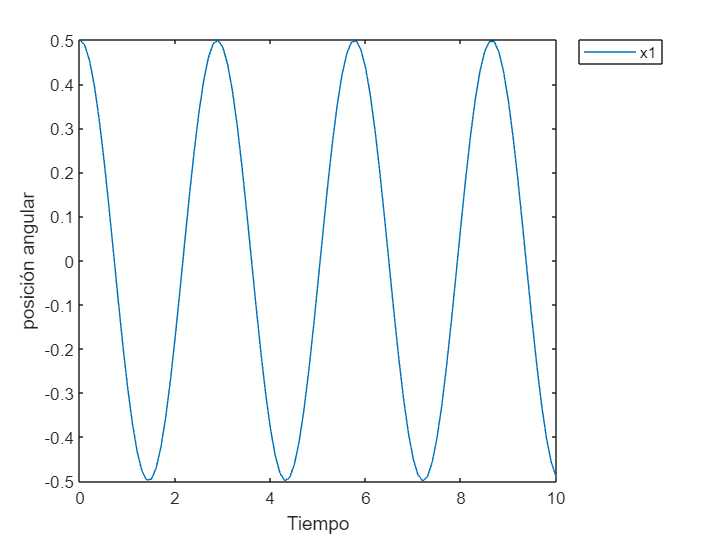

clear
syms x1(t) x2(t)

g=9.8;
l=2;
m=1;
f=0;
u=0;

%ecuaciones
ecu1= x2;
ecu2= (-g/l)* sin(x1) - (f/m)*x2 + (u/(m*l));

F= odeFunction([ecu1, ecu2], [x1, x2]);

%Condición inicial
CI= [0.5 0];

%Tiempo
t0=0;
tf=10;

%Paso
h=0.1;
t=t0:h:tf;

[t, Sol]= ode45 (F, t, CI);

x1_Sol= Sol(:,1);
x2_Sol= Sol(:,2); 

%Gráfica
figure
plot(t, x1_Sol)
xlabel ("Tiempo")
ylabel ("posición angular")
legend ("x1", "Location", "bestoutside")

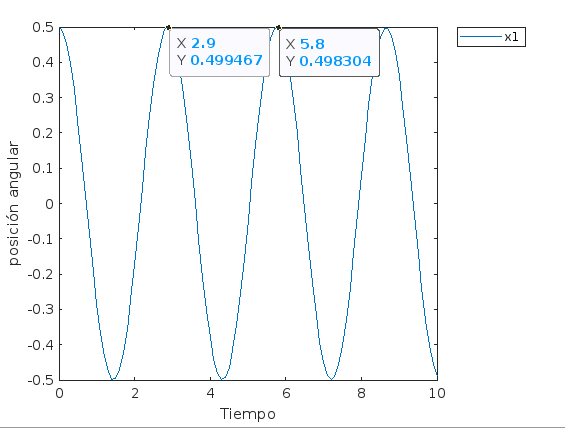

**Solución analítica:**

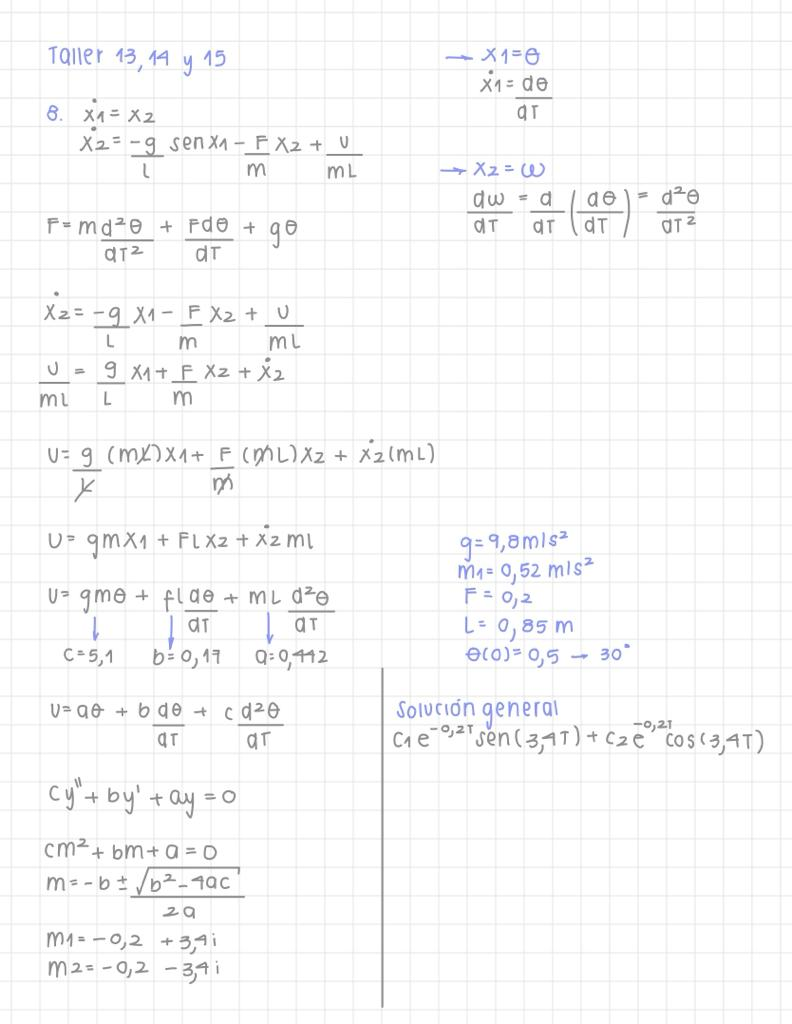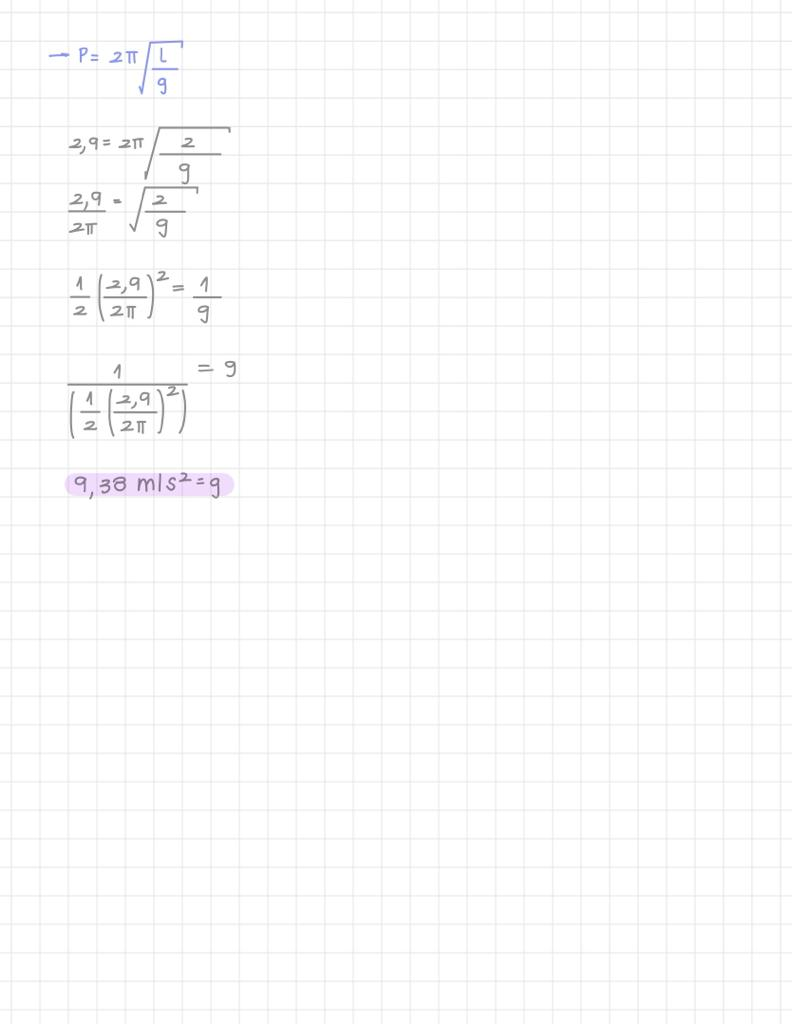

**Conclusión:**

- Realizamos esta gráfica para hallar el valor del periodo, ¿Cómo? Tomamos el valor en y del segundo pico y se le restó el valor de y del primer pico. Es decír: 5.8-2.9= 2.9.

- Coneste valor y con las fórmulas dadas, podemos hallar el valor de la gravedad a modo de comprobación, y podemos hacer lo mismo con la longitud.

**PUNTO 9.**

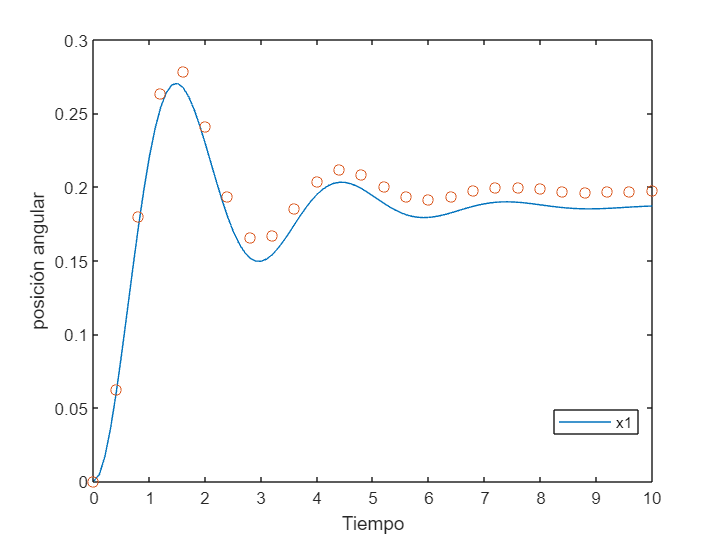

theta_exp =  [0
        0.0621
        0.1797
        0.2635
        0.2783
        0.2414
        0.1932
        0.1656
        0.1667
        0.1852
        0.2038
        0.2119
        0.2086
        0.2002
        0.1934
        0.1915
        0.1938
        0.1973
        0.1997
        0.1999
        0.1987
        0.1972
        0.1965
        0.1966
        0.1972
        0.1978];
t_exp=  [0
        0.4000
        0.8000
        1.2000
        1.6000
        2.0000
        2.4000
        2.8000
        3.2000
        3.6000
        4.0000
        4.4000
        4.8000
        5.2000
        5.6000
        6.0000
        6.4000
        6.8000
        7.2000
        7.6000
        8.0000
        8.4000
        8.8000
        9.2000
        9.6000
        10.0000];

syms x1(t) x2(t)

g=9.8;
l=2;
m=0.55;
f=0.6;
u=1;


%ecuaciones
ecu1= x2;
ecu2= (-g/l)* sin(x1) - (f/m)*x2 + (u/(m*l));


F= odeFunction([ecu1, ecu2], [x1, x2]);

%Tiempo
t0=0;
tf=10;

%Paso
h=0.1;
t=t0:h:tf;


%Condición inicial
CI= [0,0];

[t, Sol]= ode45 (F, t, CI);

x1_Sol= Sol(:,1);

%Gráfica
figure
plot(t, x1_Sol)
hold on
plot(t_exp, theta_exp, 'o')
xlabel ("Tiempo")
ylabel ("posición angular")
legend ("x1", "Location", "best")

**Conclusión:**

- Realizamos difentes cambios en los valores de las variables "f" y "m". Esto con el fin de lograr aproximar la gráfica azul a los puntos rojos dados.

- Estos cambios los realizamos con el fin de observar lo que ocurre y como esto varía el equilibrio del sistema.

- Variar la masa modifica la gráfica en el eje y.

- Variar la fricción modifica la gráfica en el eje x.

**PUNTO 10.**

**Parámetros:**

- Largo eje: 85cm

- Condición inicial theta 1: 30°

- Condición inicial theta 2: 45°

- **Masa 1: 520.3 g **

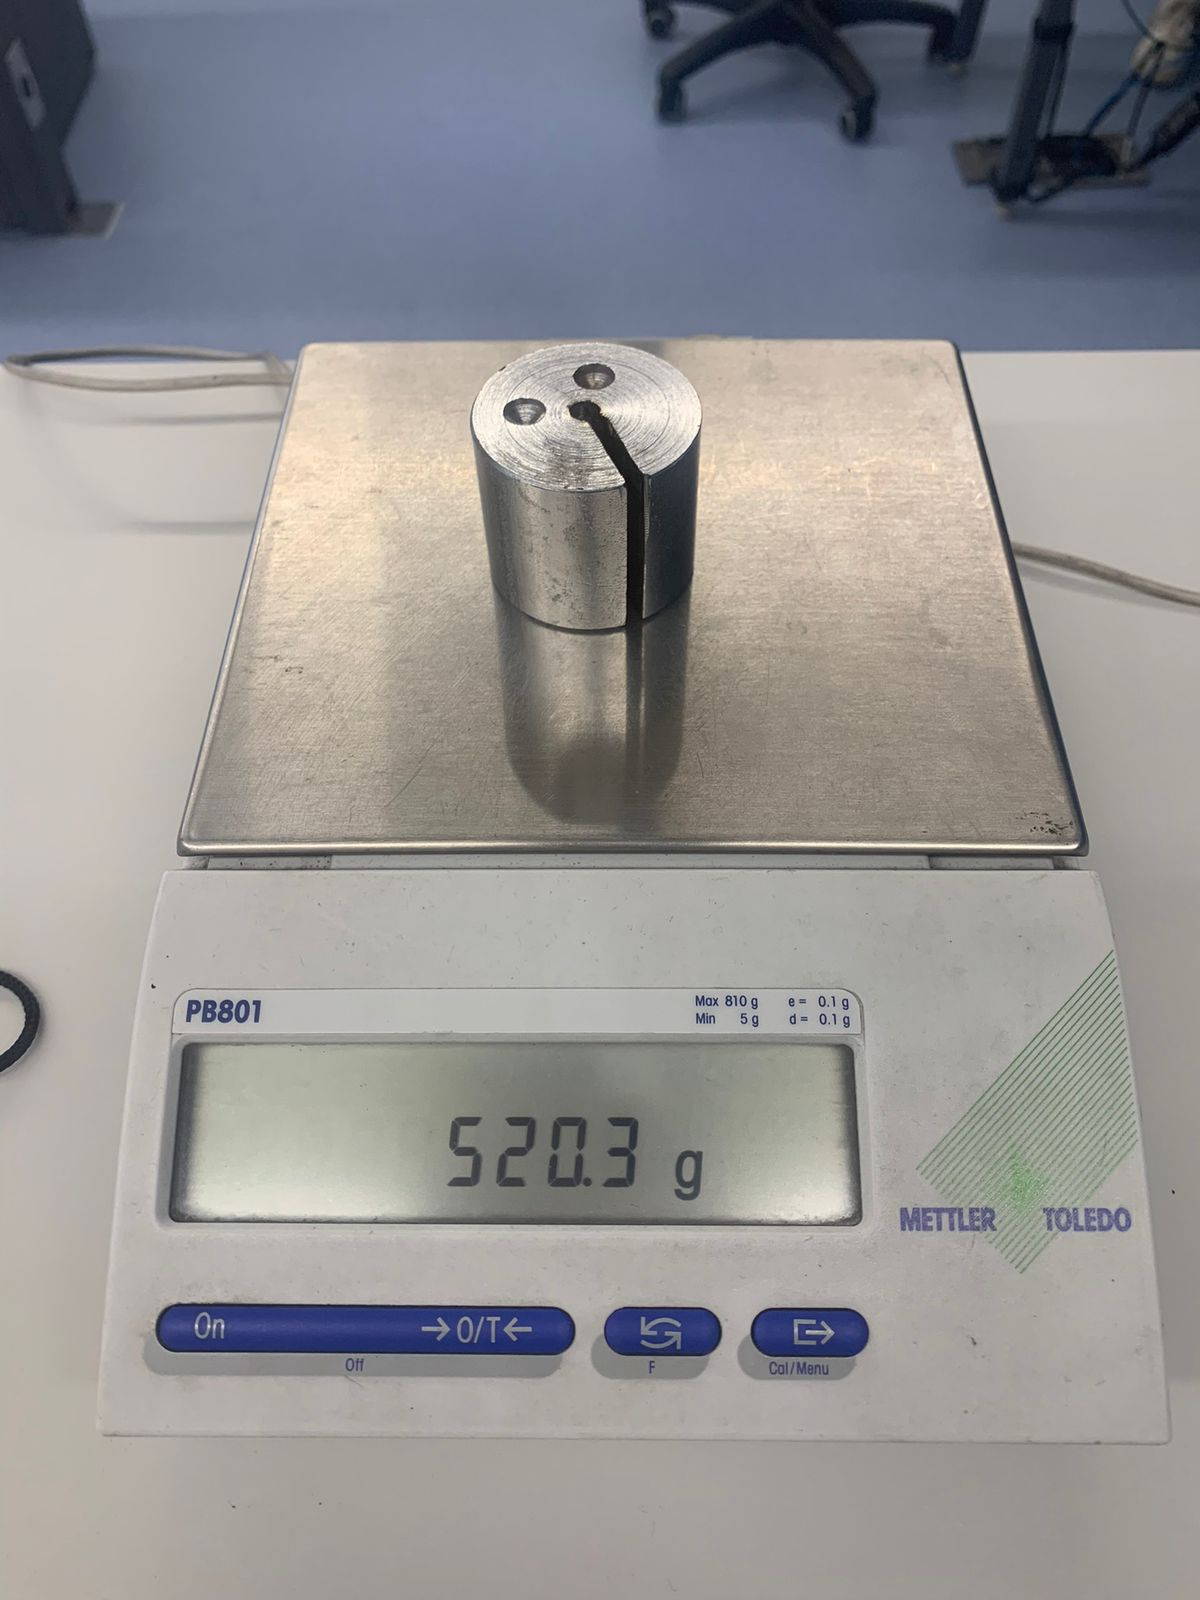

- 30° tiempo: 11 min 15 seg.

- 45° tiempo: 12:25min

- **Masa 2: 68.9 g**

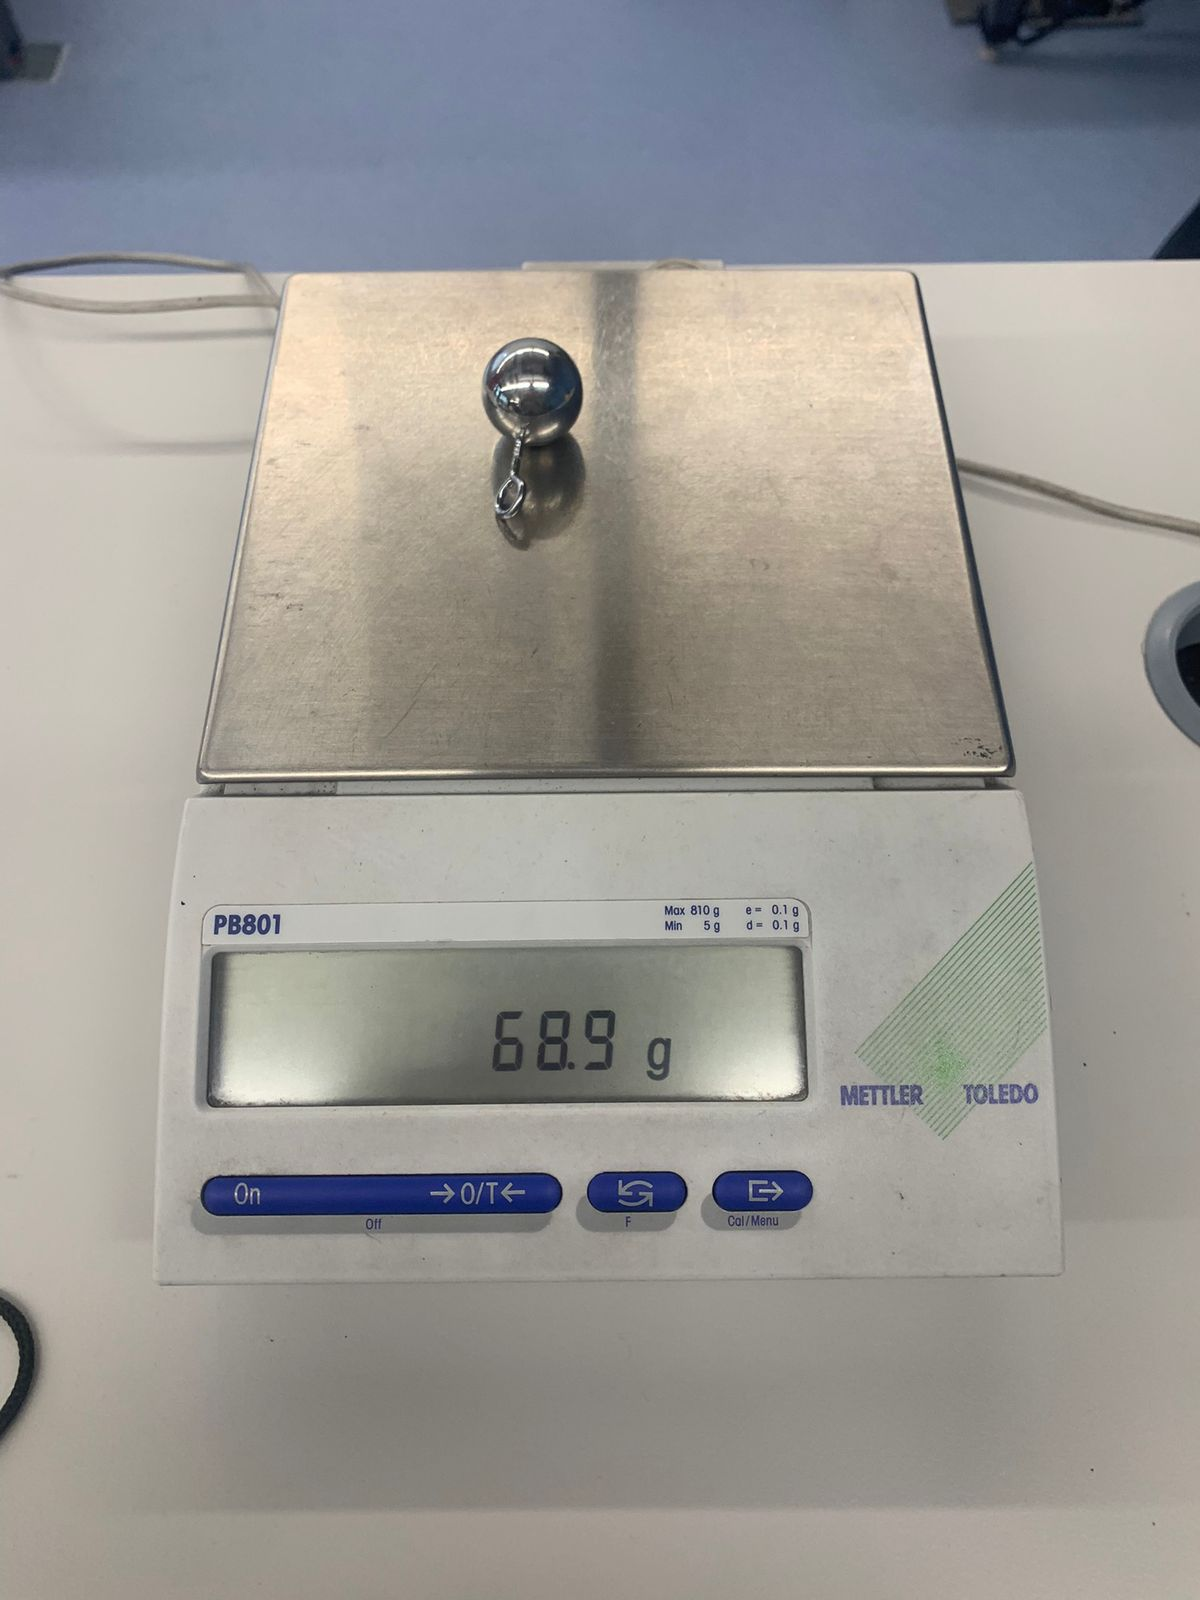

- 30° tiempo: 3:15min

- 45° tiempo: 3:52 min

- **Masa 3: 29.2g**

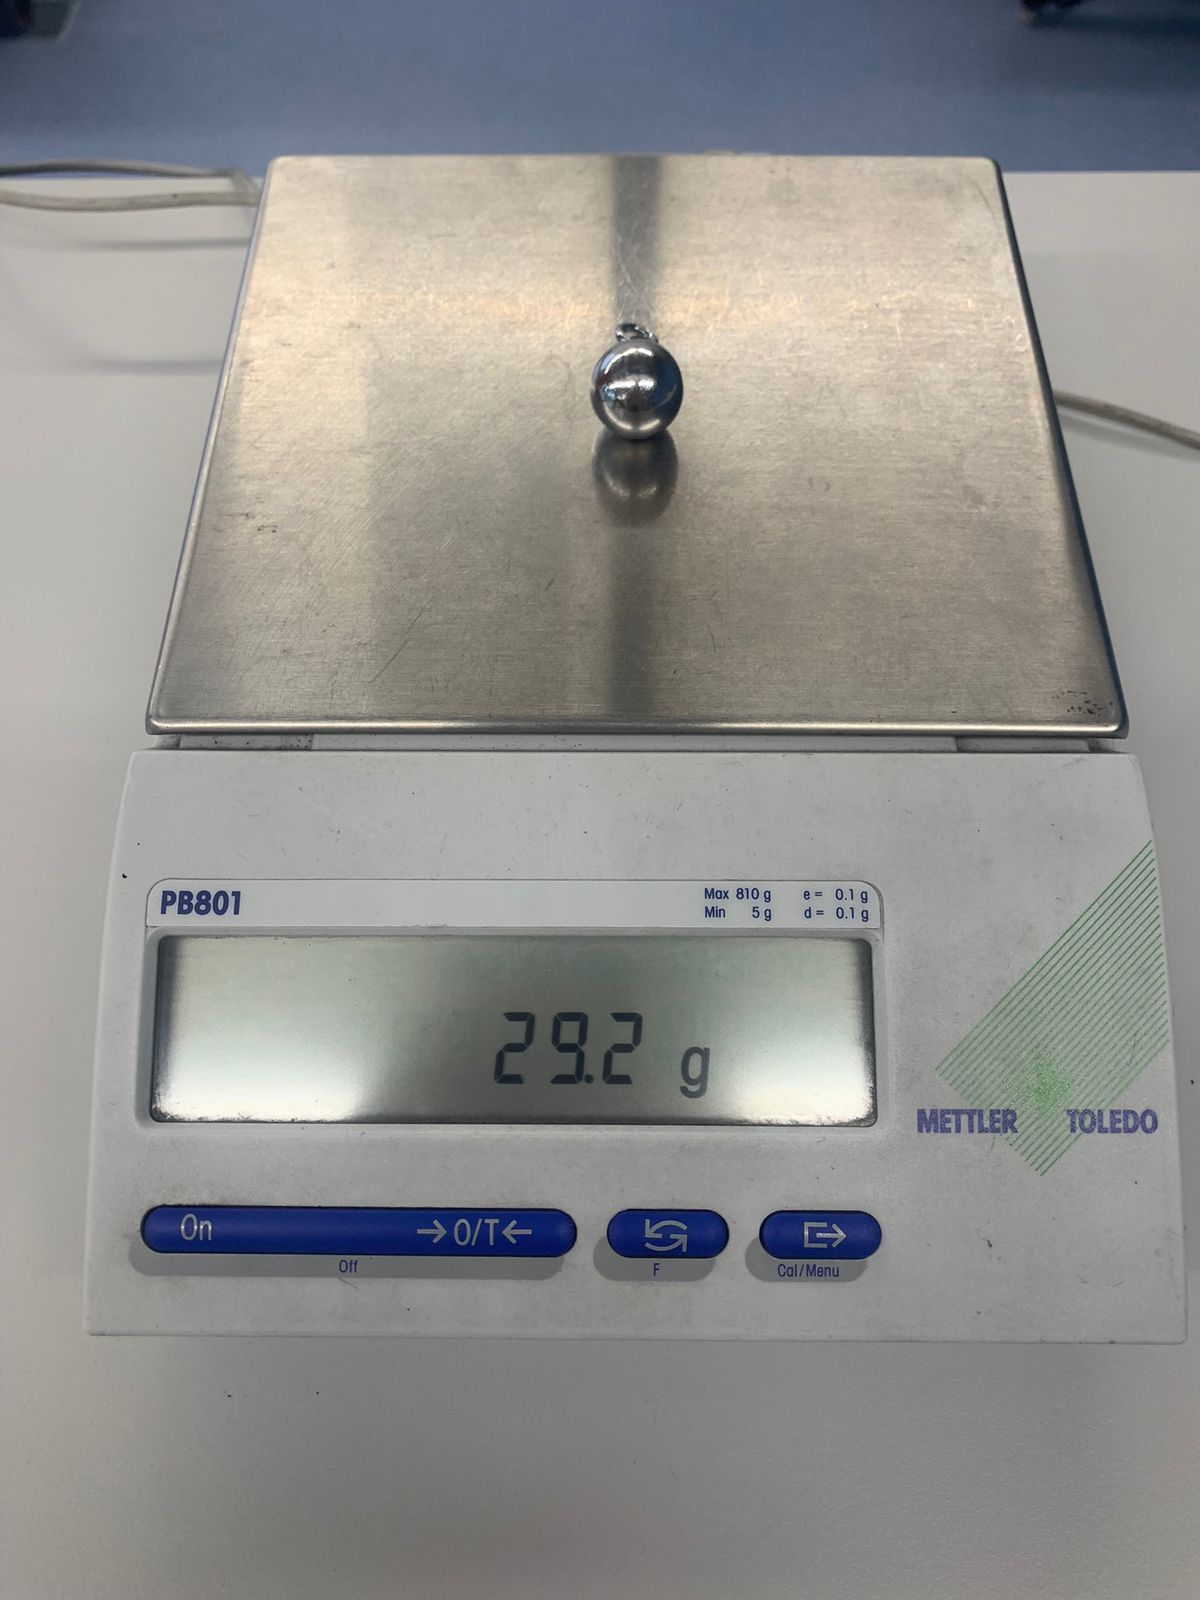

- 30° tiempo: 3.17min

- 45° tiempo: 3.48

**Enlace de video donde se muestra todo el proceso del experimento:  **[https://www.youtube.com/watch?v=EhraoKvgXVM](https://www.youtube.com/watch?v=EhraoKvgXVM)

**Conclusiones: **

- Observamos que cuando la masa del péndulo es mayor, tarda más tiempo en detenerse, igual que cuando se lanza desde un ángulo mayor (en este caso 45°) tarda más tiempo en estabilizarse que cuando se lanza a 30°. Y a medida que disminuimos el valor de la masa en cada caso, se demoraba cada vez menos en detenerse.

- Estos resultados son consistentes con los obtenidos en el programa Math Lab. En resumen, se comprobó que cuando aumenta el ángulo de oscilación o la masa es mayor, el péndulo tarda más tiempo en completar su movimiento de oscilación, lo que coincide con los análisis hechos en el programa.